Para los ejercicios 1 y 2 vamos a utilizar una misma imagen.

I = imread('.\Media\imatge.jpg');

Error using imread>get_full_filename (line 568)
File ".\Media\imatge.jpg" does not exist.

Error in imread (line 377)
    fullname = get_full_filename(filename);

imshow(I);

Output del ejercicio 1:

ejercicio_1(I);

Output del ejercicio 2:

ejercicio_2(I);
xlim([0 255])
ylim([0 7257])

Histograma original, para poder comparar:

imhist(rgb2gray(I));

Para la realización de este ejercicio hemos utilizado dos imagenes con distinta textura para poder realizar una comparacion:

I2=imread('.\Media\textura.jpg');
I3=imread('.\Media\mtextura.jpg');

imshow(I2);
imshow(I3);

Output del ejercicio 3 para la fotografia con mayor textura:

ejercicio_3(I2);

Al final con los resultados obtenemos la siguiente tabla:

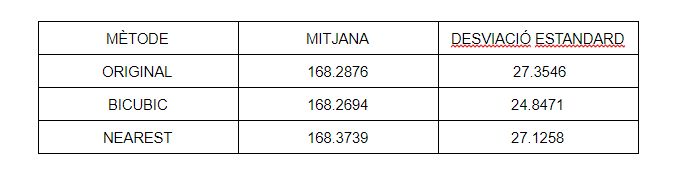

Output del ejercicio 3 para la fotografia con menor textura:

ejercicio_3(I3);

Al final con los resultados obtenemos la siguiente tabla:

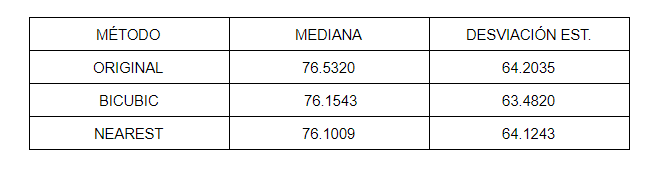

Output del ejercicio 4:

A = imread('.\Media\imatgeA.jpg');
B = imread('.\Media\imatgeB.jpg');

En este caso realizaremos 2 ejecuciones distintas con las mismas imagenes cambiando la matriz de transformacion.

- En la primera ejecucion mostramos el output tras una transformamos neutra a la imagen A:

T = affine2d([1 0 0; 0 1 0; 0 0 1]);
ejercicio_4(A,B,T);

- En la segunda ejecucion mostramos el output con la imagen A transformada por una matriz no neutra.

T = affine2d([1 0 0; 0.5 1 0; 0 0 1]);
ejercicio_4(A,B,T);